# Kalman Filter Plots

## Data Prep

bnd = 1;


## Noise from a 440 Hz Sine Wave

start = 500;
stop = 1500;
T = 0.070;
data = SineWave440.RawMeasurement(start:stop);

Undefined variable "SineWave440" or class "SineWave440.RawMeasurement".

filtered = SineWave440.FilteredValue(start:stop);

StanDev = std(data)
Var = var(data)

time = [];
foo = 0;
for i = 1:length(data)
    time(i) = foo;
    foo = foo + T;
end
    
figure
plot(time,data)
title('Raw Measurement of a 440 Hz Sine Wave')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
xlim([0 time(end)])
hold on
hline = refline(0,440);
hline.Color = 'k';
hline.LineStyle = '-';
hline.LineWidth = 1.75;

figure
standev_text = sprintf('Standard Deviation: σ = %.4f',StanDev);
var_text = sprintf('Variance: σ^{2} = %.4f',Var);
txt = {standev_text,var_text};

hist(data,30)
dim = [0.5 0.75 0.3 0.3];
str = {'Straight Line Plot','from 1 to 10'};
annotation('textbox',dim,'String',txt,'FitBoxToText','on','VerticalAlignment','bottom');
title('Measurement Noise Histogram')
xlabel('Pitch (Hz)')
ylabel('Frequency')

figure
plot(time,data)
title('Raw and Filtered Measurement of a 440 Hz Sine Wave')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
xlim([0 time(end)])
hold on
plot(time,filtered)
hline = refline(0,440);
hline.Color = 'k';
hline.LineStyle = '-';
hline.LineWidth = 1.00;
legend('Raw Data','Filtered Data')

## Noise from a Violin's A String

start = 1;
stop = 240;
data = ViolinAConst.RawMeasurement(start:stop);
filtered = ViolinAConst.FilteredValue(start:stop);

StanDev = std(data)

StanDev = 0.6687

Var = var(data)

Var = 0.4472

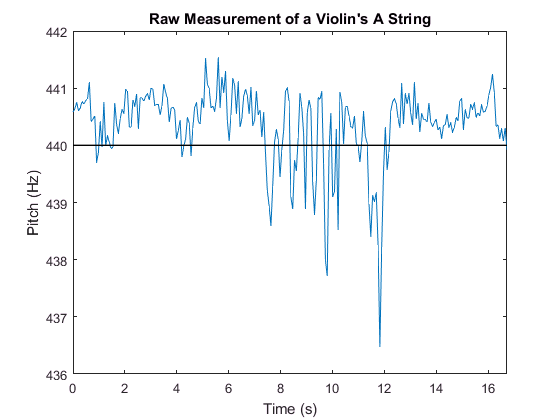


T = 0.070;
time = [];
foo = 0;
for i = 1:length(data)
    time(i) = foo;
    foo = foo + T;
end

figure
plot(time,data)
title('Raw Measurement of a Violin''s A String')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
xlim([0 time(end)])
hold on
hline = refline(0,440);
hline.Color = 'k';
hline.LineStyle = '-';
hline.LineWidth = 1.00;

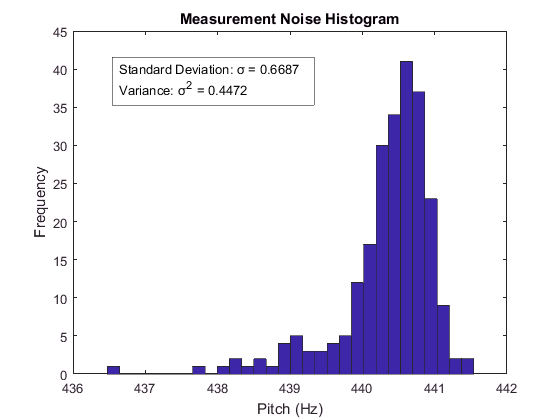


figure
standev_text = sprintf('Standard Deviation: σ = %.4f',StanDev);
var_text = sprintf('Variance: σ^{2} = %.4f',Var);
txt = {standev_text,var_text};

hist(data,30)
dim = [0.2 0.75 0.3 0.3];
str = {'Straight Line Plot','from 1 to 10'};
annotation('textbox',dim,'String',txt,'FitBoxToText','on','VerticalAlignment','bottom');
title('Measurement Noise Histogram')
xlabel('Pitch (Hz)')
ylabel('Frequency')

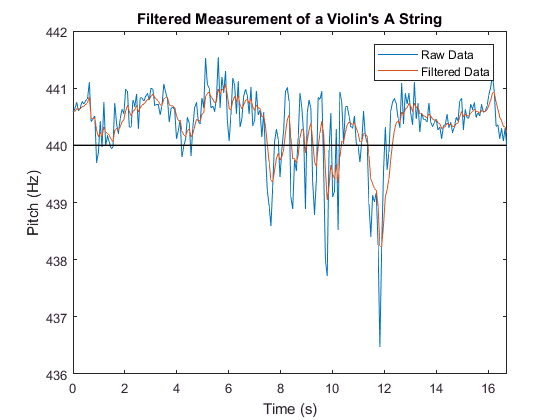


figure
plot(time,data)
title('Filtered Measurement of a Violin''s A String')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
xlim([0 time(end)])
hold on
plot(time,filtered)
hline = refline(0,440);
hline.Color = 'k';
hline.LineStyle = '-';
hline.LineWidth = 1.00;
legend({'Raw Data','Filtered Data'},'Location','northeast')

## Closed Loop Flat Start

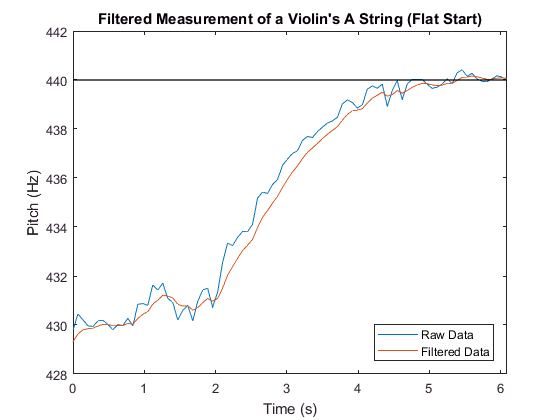

data = ViolinTuneFS.RawMeasurement;
filtered = ViolinTuneFS.FilteredValue;

T = 0.070;
time = [];
foo = 0;
for i = 1:length(data)
    time(i) = foo;
    foo = foo + T;
end

figure
plot(time,data)
title('Filtered Measurement of a Violin''s A String (Flat Start)')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
xlim([0 time(end)])
hold on
plot(time,filtered)
hline = refline(0,440);
hline.Color = 'k';
hline.LineStyle = '-';
hline.LineWidth = 1.00;
legend({'Raw Data','Filtered Data'},'Location','southeast')

## Closed Loop Sharp Start

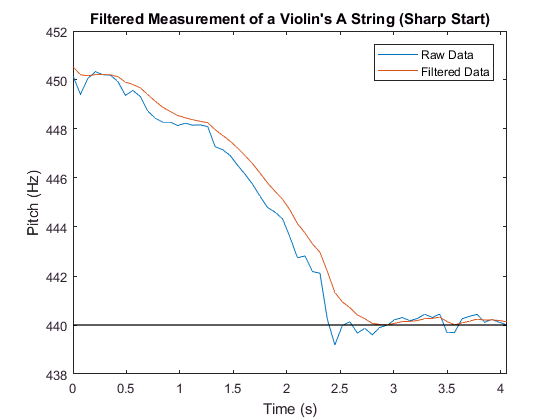

data = ViolinTuneSS.RawMeasurement;
filtered = ViolinTuneSS.FilteredValue;

T = 0.070;
time = [];
foo = 0;
for i = 1:length(data)
    time(i) = foo;
    foo = foo + T;
end

figure
plot(time,data)
title('Filtered Measurement of a Violin''s A String (Sharp Start)')
xlabel('Time (s)')
ylabel('Pitch (Hz)')
xlim([0 time(end)])
hold on
plot(time,filtered)
hline = refline(0,440);
hline.Color = 'k';
hline.LineStyle = '-';
hline.LineWidth = 1.00;
legend({'Raw Data','Filtered Data'},'Location','northeast')